Exercise 1c.

Does this match the predicted anwser from a?  hell yeah it does

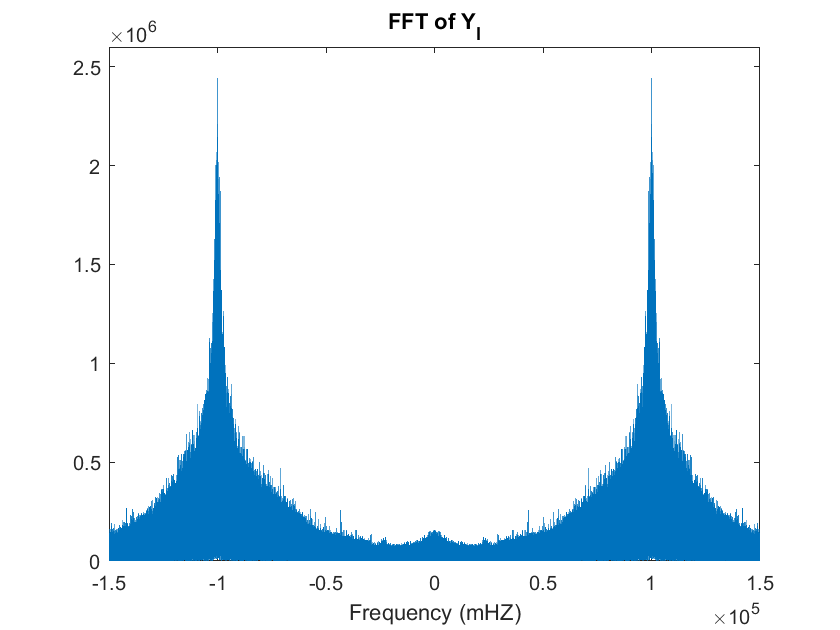

load('data_exercise1c.mat');
figure;
plot_FT(y_I,fs);
xlabel('Frequency (mHZ)');
ylim([0,2.6*10^6])
title('FFT of Y_I');
hold off;

Exercise 1d.

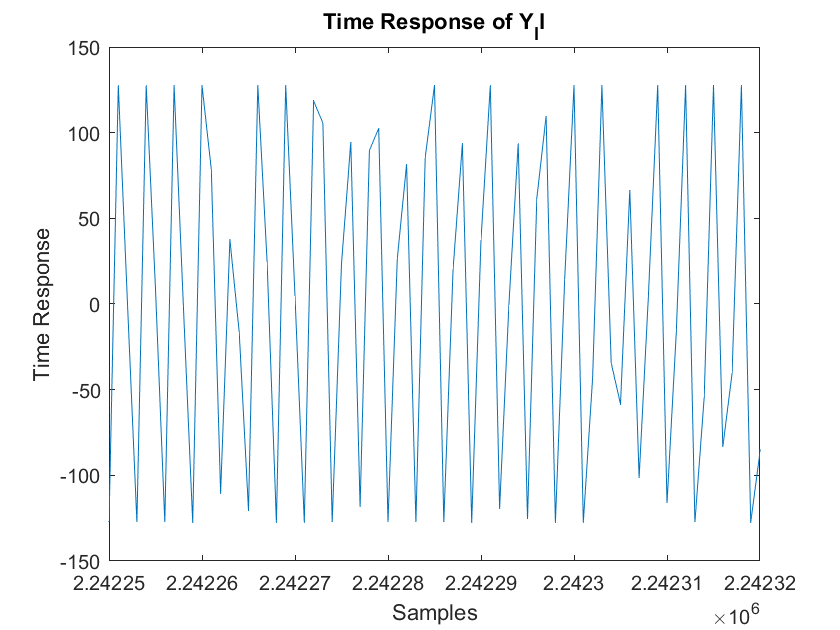

clf;
figure;
plot(y_I)
xlabel('Samples');
xlim([2.24225*10^6,2.24232*10^6])
ylabel('Time Response');
title('Time Response of Y_II');

Exercise 1e.

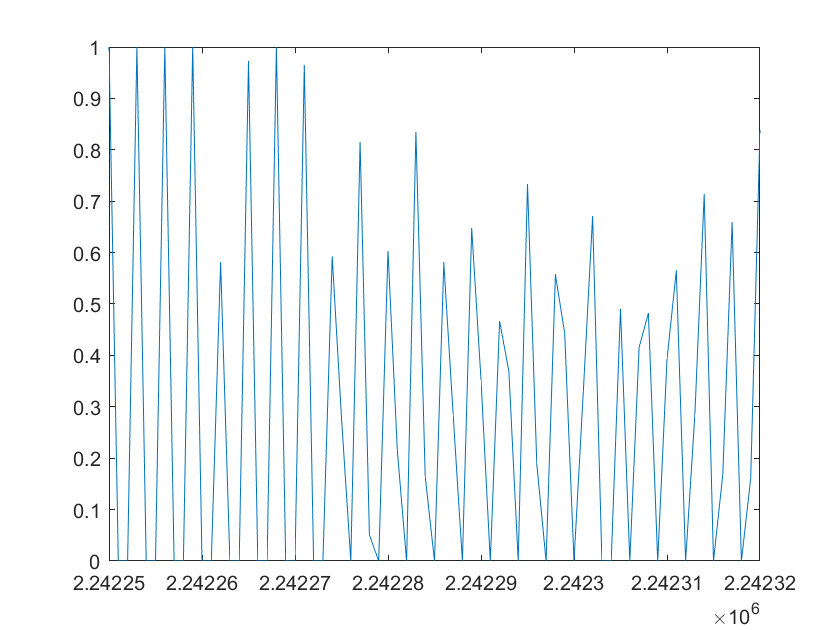

deriv = diff(y_I);
deriv(deriv<0) = 0;
deriv = deriv./max(deriv);
plot(deriv)
xlim([2.24225*10^6,2.24232*10^6])

Exercise 1f.

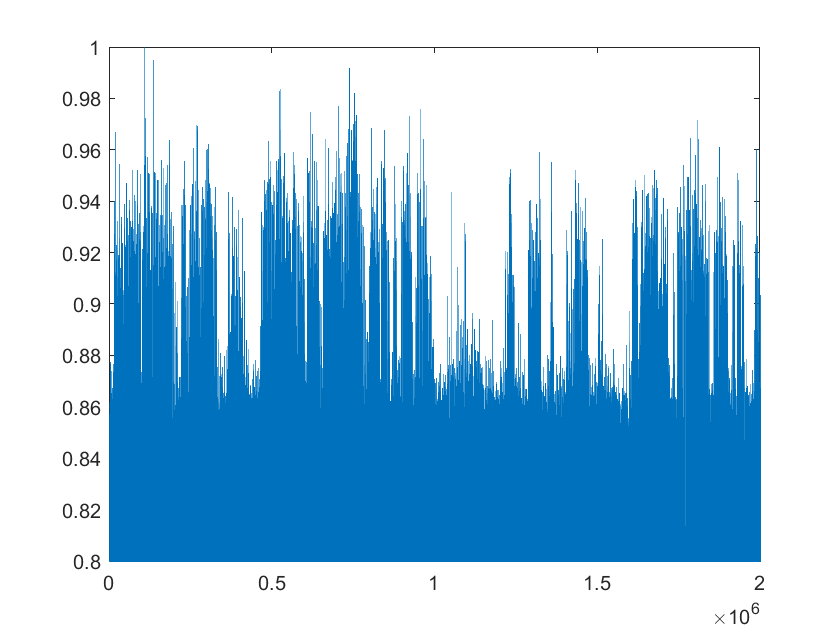

y = lowpass(deriv, 1.5^5, fs);
y = y./max(y);
plot(y);
xlim([0, 2*10^6]);
ylim([.8, 1]);

Exercise 1g.

y = y - mean(y);
y = (y./max(y)).*.1;
y = decimate(y, 4);
sound(y, 300000/4);